Consider Charney–DeVore model [1,2]


$$\dot{z}_1=\gamma_1^\ast z_3-C(z_1-z_1^\ast),\\
\dot{z}_2=-(\alpha_1z_1-\beta_1)z_3-Cz_2-\delta_1z_4z_6,\\
\dot{z}_3=(\alpha_1z_1-\beta_1)z_2-\gamma_1z_1-Cz_3+\delta_1z_4z_5,\\
\dot{z}_4=\gamma_2^\ast z_6-C(z_4-z_4^\ast)+\epsilon(z_2z_6-z_3z_5),\\
\dot{z}_5=-(\alpha_2z_1-\beta_2)z_6-Cz_5-\delta_2z_4z_3,\\
\dot{z}_6=(\alpha_2z_1-\beta_2)z_5-\gamma_2z_4-Cz_6+\delta_2z_4z_2.$$


The model coefficients are given by


$$\alpha_m=\frac{8\sqrt{2}}{\pi}\frac{m^2}{4m^2-1}\frac{b^2+m^2-1}{b^2+m^2},\quad \beta_m=\frac{\beta b^2}{b^2+m^2},\\
\delta_m=\frac{64\sqrt{2}}{15\pi}\frac{b^2-m^2+1}{b^2+m^2},\quad \gamma_m^\ast = \gamma \frac{4m}{4m^2-1}\frac{\sqrt{2}b}{\pi},\\
\epsilon=\frac{16\sqrt{2}}{5\pi},\gamma_m=\gamma\frac{4m^3}{4m^2-1}\frac{\sqrt{2}b}{\pi(b^2+m^2)}.$$


[1] Crommelin, Daan T., J. D. Opsteegh, and F. Verhulst. "A mechanism for atmospheric regime behavior." *Journal of the atmospheric sciences* 61.12 (2004): 1406-1419.

[2] Babaee, Hessam, et al. "Reduced-order description of transient instabilities and computation of finite-time Lyapunov exponents." *Chaos: An Interdisciplinary Journal of Nonlinear Science* 27.6 (2017): 063103.

## Continuation of fixed point

We first calculate the fixed points of the system above. Later, we will take some of these fixed points as the anchor point for SSM reduction. Next we use parameter continuation to reproduce the right panel of Fig.1 of ref. [1].

clear all;
x0 = zeros(6,1);
p0 = 0;
prob = coco_prob();
prob = coco_set(prob, 'cont', 'PtMX', 200);
prob = ode_isol2ep(prob, '', @CharneyDeVore, x0, 'z1ast', p0);
prob = coco_add_pars(prob, 'z1', 1, 'z1', 'active');
coco(prob, 'cont-ep', [], 1, {'z1ast' 'z1'}, [0,10]);


    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          0.00e+00  0.00e+00    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE         z1ast           z1
    0  00:00:00   0.0000e+00      1  EP      0.0000e+00   0.0000e+00
   10  00:00:01   8.9041e-01      2          5.5741e-01   2.2152e-01
   20  00:00:01   5.6952e+00      3          3.8469e+00   6.8571e-01
   30  00:00:01   1.0599e+01      4          7.2697e+00   9.0663e-01
   40  00:00:01   1.2454e+01      5          8.5440e+00   1.0571e+00
   44  00:00:02   1.2471e+01      6  FP      8.5525e+00   1.0703e+00
   44  00:00:02   1.2471e+01      7  SN      8.5525e+00   1.0703e+00
   50  00:00:02   1.2427e+01      8          8.5125e+00   1.0998e+00
   60  00:00:02   1.1649e+01      9          7.9316e+00   1.1973e+00
   70  00:00:03   7.3756e+00     10          4.7336e+00   1.5913e+00
   80  00:00:03   5.8496e+00 

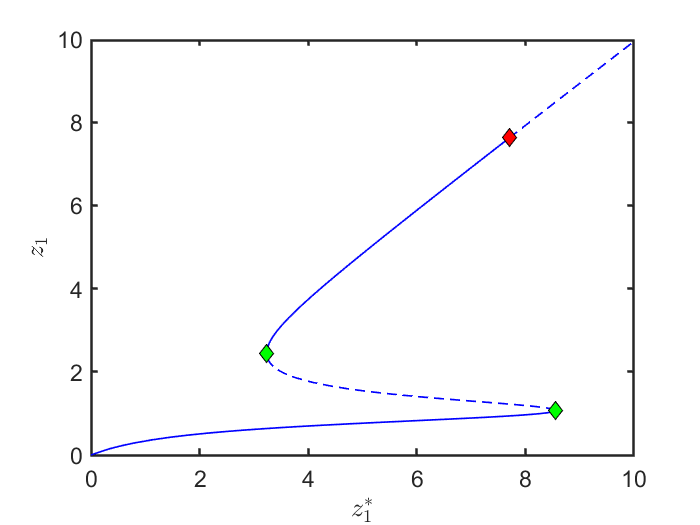

% continuation path of fixed points
figure;
thm = struct('special', {{'SN','HB'}});
coco_plot_bd(thm,'cont-ep', 'z1ast', 'z1')
set(gca,'fontsize',14);
set(gca,'LineWidth',1.5);
xlabel('$z_1^\ast$','interpreter','latex');
ylabel('$z_1$','interpreter','latex');

As seen above, two saddle-node bifurcations and a Hopf bifurcation are detected along the manifold of fixed points. Therefore, all points on the middle unstable branch are rank-1 saddles, and the unstable fixed points after the Hopf bifurcation are rank-2 saddles. 

## Shift origin to a rank-1 saddle and calcualte the SSM around the saddle

% we take the solution with label 10 as the anchor point for SSM reduction.
% read solution
lab = 10;
sol = ep_read_solution('', 'cont-ep', lab);
% build model with shifed origin
[A,B,F] = build_model(sol);
% setup dynamical system
DS = DynamicalSystem();
set(DS,'A',A,'B',B,'fnl',F); 
set(DS.Options,'notation','tensor')
% spectrum analysis
[V,D,W] = DS.linear_spectral_analysis();


 The first 6 eigenvalues are given as 
   0.1948 + 0.0000i
  -0.0988 + 3.0348i
  -0.0988 - 3.0348i
  -0.1012 + 0.0000i
  -0.2480 + 0.1576i
  -0.2480 - 0.1576i



% construct SSM
S = SSM(DS);
set(S.Options,'paramStyle','graph','reltol',1)
set(S.Options,'notation','tensor');
masterModes = 1;                        % master mode
order = 9;                              % SSM expansion order
S.choose_E(masterModes);

sigma_out = -1
sigma_in = -1


[W0,R0] = S.compute_whisker(order);     % compute of SSM

Computing autonomous whisker at order 2
0 (near) inner resonance(s) detected at order 2
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 7.04E-03 MB
Computing autonomous whisker at order 3
0 (near) inner resonance(s) detected at order 3
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 9.90E-03 MB
Computing autonomous whisker at order 4
0 (near) inner resonance(s) detected at order 4
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 1.16E-02 MB
Computing autonomous whisker at order 5
0 (near) inner resonance(s) detected at order 5
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 1.33E-02 MB
Computing autonomous whisker at order 6
0 (near) inner resonance(s) detected at order 6
Manifold computation time at order 6 = 00:00:00
Estimated memory usage at order  6 = 1.51E-02 MB
Computing autonomous whisker at order 7
0 (near) inner resonance(s) detecte

As seen above, no inner resonances are detected in the computation of SSM. So the reduced dynamics is linear: $\dot{p}=\lambda_1p$.

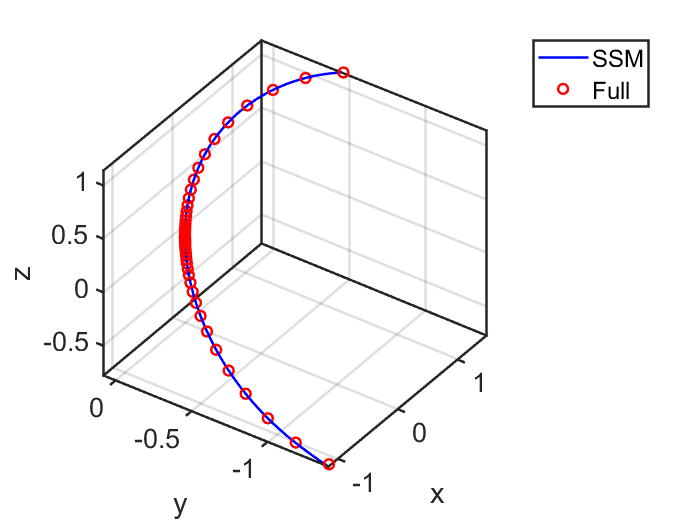

lamdMaster = D(masterModes,masterModes);
tf = 52;
t  = linspace(0,tf,200);
p1 = 1e-4*exp(lamdMaster*t); 
% mapping to full system
z1 = reduced_to_full_traj(t,p1,W0);
% repeat the above for a different initial condition
p2 = -1e-4*exp(lamdMaster*t);
z2 = reduced_to_full_traj(t,p2,W0);
z  = [z2(:,end:-1:1) z1];
% plot SSM
figure;
plot3(z(1,:),z(2,:),z(3,:),'b-','LineWidth',1.5); grid on
xlabel('x'); ylabel('y'); zlabel('z');
set(gca,'fontsize',16);
set(gca,'LineWidth',1.5);
box on; view([-55,38])
axis tight

% forward simulation of the original system
zinit_plus = V(:,1)*1e-4;
zinit_minu = -zinit_plus;
odefunc = @(t,z) DS.odefun(t,z);
[tplus,zplus] = ode45(odefunc,0:1:tf,zinit_plus);
[tminu,zminu] = ode45(odefunc,0:1:tf,zinit_minu);
zfull = [zminu(end:-1:1,:);zplus];
% plot simulated orbits
hold on
plot3(zfull(:,1),zfull(:,2),zfull(:,3),'ro','LineWidth',1.5);
legend('SSM','Full')

## Shift origin to a rank-2 saddle and calcualte the SSM around the saddle

% we take the solution with label 19 as the anchor point for SSM reduction.
% read solution
clear all;
lab = 19;
sol = ep_read_solution('', 'cont-ep', lab);
[A,B,F] = build_model(sol);
DS = DynamicalSystem();
set(DS,'A',A,'B',B,'fnl',F); 
set(DS.Options,'notation','multiindex')

%Linear Modal analysis and SSM computation
[V,D,W] = DS.linear_spectral_analysis();


 The first 6 eigenvalues are given as 
   0.6480 + 4.7288i
   0.6480 - 4.7288i
  -0.0982 + 0.0000i
  -0.1001 + 0.0000i
  -0.8488 + 4.7248i
  -0.8488 - 4.7248i



% the eigenvalues above should be consistent with the ons in sol.ep_test.la
 
% now we compute the 2D SSM
S = SSM(DS);
set(S.Options, 'reltol', 1.0,'notation','multiindex');
resonant_modes = [1 2]; % choose master spectral subspace
order = 11;                  % SSM expansion order
S.choose_E(resonant_modes)

sigma_out = -1
sigma_in = -1


[W0,R0] = S.compute_whisker(order);

Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 1.16E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 1.43E-02 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 1.72E-02 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 2.21E-02 MB
Manifold computation time at order 6 = 00:00:00
Estimated memory usage at order  6 = 2.72E-02 MB
Manifold computation time at order 7 = 00:00:00
Estimated memory usage at order  7 = 3.50E-02 MB
Manifold computation time at order 8 = 00:00:00
Estimated memory usage at order  8 = 4.31E-02 MB
Manifold computation time at order 9 = 00:00:00
Estimated memory usage at order  9 = 5.27E-02 MB
Manifold computation time at order 10 = 00:00:00
Estimated memory usage at order  10 = 6.62E-02 MB
Manifold computation time at order 11 = 00:00:00
Estimated memory usage at order  11 = 7.99E-02 MB


Reduced dynamics in symbolic form

lamdMaster = DS.spectrum.Lambda(resonant_modes);
options = struct();
options.isauto = true; 
options.isdamped = true;
options.numDigits = 4;
disp('Reduced dynamics on the 2D unstable SSM:')

Reduced dynamics on the 2D unstable SSM:


y = reduced_dynamics_symbolic(lamdMaster,R0,options)

$$y = \left(\begin{array}{c} -0.4963\,{\rho_{1}}^{7}-0.4259\,{\rho_{1}}^{5}-0.6239\,{\rho_{1}}^{3}+0.648\,\rho_{1}\\ 0.001089\,{\rho_{1}}^{6}+0.0006939\,{\rho_{1}}^{4}+0.0006916\,{\rho_{1}}^{2}+4.729 \end{array}\right)$$

Visualization of the 2D unstable SSM

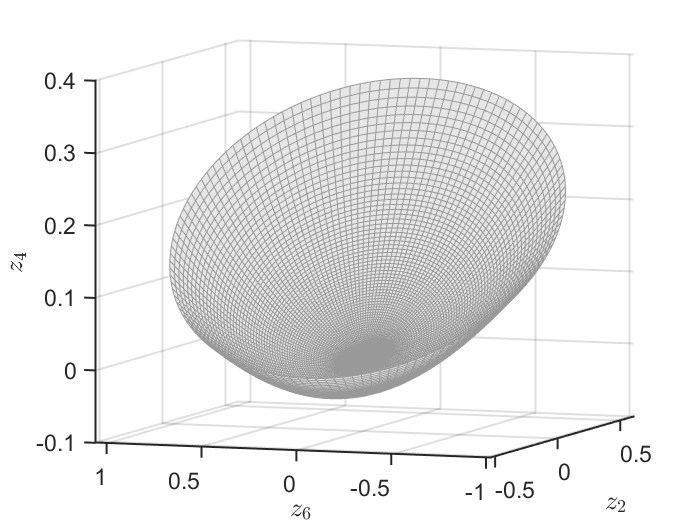

rhosamp = [0 0.05 0.08:0.01:0.7];
plotdofs = [2 6 4]; 
plot_2D_auto_SSM(W0,rhosamp,plotdofs,{'$z_2$','$z_6$','$z_4$'});
view([-70 7])

figssm = gcf;

 validation of SSM prediction

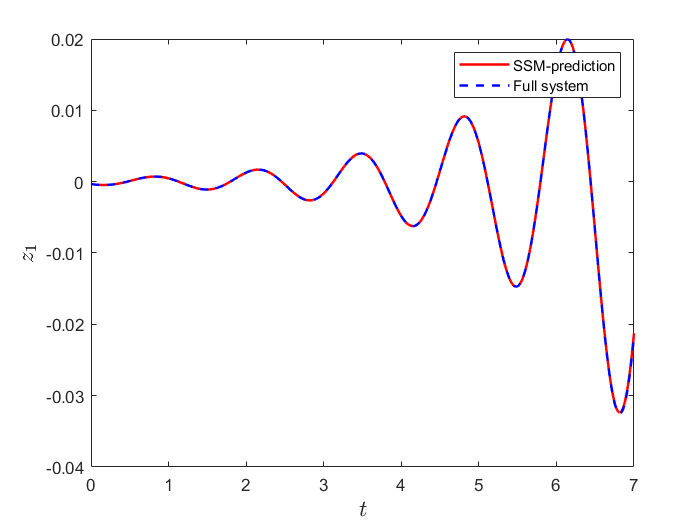

% plot transient trajectories on the SSM
tf = 7;
nsteps = 1000;
q0 = 0.01*exp(1i*0.5);
q0 = [q0;conj(q0)];
z0 = reduced_to_full_traj(0,q0,W0);
traj = transient_traj_on_auto_ssm(DS, resonant_modes, W0, R0, tf, nsteps, 1:6, [], q0);

% Reference solution from forward simulation
options = odeset('RelTol',1e-8,'AbsTol',1e-10);
odefun  = @(t,z) DS.odefun(t,z);
[tInt1, zInt1] = ode15s(odefun, [0 tf], z0(1:6),options); 

figure;
plot(traj.time,traj.phy(:,1),'r-','LineWidth',1.5); hold on
plot(tInt1,zInt1(:,1),'b--','LineWidth',1.5);
legend('SSM-prediction','Full system')
xlabel('$t$','Interpreter',"latex",'FontSize',14);
ylabel('$z_1$','Interpreter',"latex",'FontSize',14);

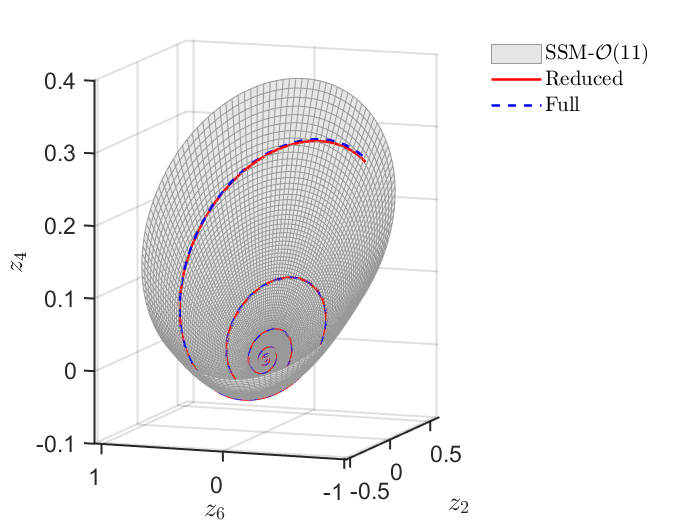


figure(figssm); hold on
hold on
plot3(traj.phy(:,plotdofs(1)),traj.phy(:,plotdofs(2)),traj.phy(:,plotdofs(3)),'r-','LineWidth',1.5);
plot3(zInt1(:,plotdofs(1)),zInt1(:,plotdofs(2)),zInt1(:,plotdofs(3)),'b--','LineWidth',1.5);
legend('SSM-$\mathcal{O}(11)$','Reduced','Full','interpreter','latex');
legend boxoff